# GCI calculator

sblau = [56 58 107] / 255; smag  = [203 31 115] / 255;  
srot  = [224 58 60] / 255; soran = [242, 136, 1] / 255;
lwidth = 1.5;

## Regular Calculation

### Parameters

#### Domain area

Volume = 1;    % area of domain

#### Key variables

Phi1 = 0.346716;    % finest mesh
Phi2 = 0.357382;    % medium mesh
Phi3 = 0.374473;    % coarsest mesh

#### Cell numbers

nCells1 = 140000;    % finest mesh
nCells2 = 78750;    % medium mesh
nCells3 = 35000;    % coarsest mesh

### Calculations

h1 = sqrt(Volume/nCells1)

h1 = 0.0027

h2 = sqrt(Volume/nCells2)

h2 = 0.0036

h3 = sqrt(Volume/nCells3)

h3 = 0.0053


% always h_coarse / h_fine
r21 = h2/h1

r21 = 1.3333

r32 = h3/h2

r32 = 1.5000


a=(Phi3-Phi2)/(Phi2-Phi1);
s=sign(a);
f=@(x)x-abs(log(abs(a))+log((r21^x-s)/(r32^x-s)))/log(r21);
p=fzero(f,1)

p = 0.3689

phi_ext_21=(r21^p*Phi1-Phi2)/(r21^p-1)

phi_ext_21 = 0.2515

phi_ext_32=(r32^p*Phi2-Phi1)/(r32^p-1)

phi_ext_32 = 0.4235

e21_a=abs((Phi1-Phi2)/Phi1)

e21_a = 0.0308

e21_ext=abs((phi_ext_21-Phi1)/phi_ext_21)

e21_ext = 0.3789

GCI=1.25*e21_a/(r21^p-1)

GCI = 0.3435

## For Profile

### Definitions

#### Domain area

Volume = 3.209553837;    % area of domain

#### Files

file1 = "/home/andreasthoeni/OpenFOAM/andreasthoeni-v2606/run/3D_damBreak/exports/team/fine_probes_p.csv";    % finest mesh
file2 = "/home/andreasthoeni/OpenFOAM/andreasthoeni-v2606/run/3D_damBreak/exports/team/medium_probes_p.csv";    % medium mesh
file3 = "/home/andreasthoeni/OpenFOAM/andreasthoeni-v2606/run/3D_damBreak/exports/team/coarse_probes_p.csv";    % coarsest mesh

#### Cell numbers

nCells1 = 712233;    % finest mesh
nCells2 = 211032;    % medium mesh
nCells3 = 62528;    % coarsest mesh

#### Column of interest

col = 2;

data1 = readmatrix(file1);
data2 = readmatrix(file2);
data3 = readmatrix(file3);

### Calculations

tcol = 1;
t1 = data1(:,tcol);
Phi1 = data1(:,col);

t2 = data2(:,tcol);
Phi2 = data2(:,col);

t3 = data3(:,tcol);
Phi3 = data3(:,col);

tq = [1.05344, 1.77, 2.90667, 3.964, 4.864, 5.856, 6.85333];

Phi1 = interp1(t1, Phi1, tq, 'linear');
Phi2 = interp1(t2, Phi2, tq, 'linear');
Phi3 = interp1(t3, Phi3, tq, 'linear');

h1 = (Volume/nCells1)^(1/3)

h1 = 0.0165

h2 = (Volume/nCells2)^(1/3)

h2 = 0.0248

h3 = (Volume/nCells3)^(1/3)

h3 = 0.0372


% always h_coarse / h_fine
r21 = h2/h1

r21 = 1.5000

r32 = h3/h2

r32 = 1.5000


N = length(Phi1)

N = 7

p = zeros(N,1);
e21_a = zeros(N,1);
for i = 1:N

    a=(Phi3(i)-Phi2(i))/(Phi2(i)-Phi1(i));
    s=sign(a);
    f=@(x)x-abs(log(abs(a))+log((r21^x-s)/(r32^x-s)))/log(r21);
    p(i)=fzero(f,1);
    phi_ext_21=(r21^p(i)*Phi1(i)-Phi2(i))/(r21^p(i)-1);
    phi_ext_32=(r32^p(i)*Phi2(i)-Phi3(i))/(r32^p(i)-1);
    e21_a(i)=abs((Phi1(i)-Phi2(i))/Phi1(i));
    e_ext=abs((phi_ext_21-Phi1(i))/phi_ext_21);

end
p

p =     1.0980
    0.1670
    3.4019
    0.3917
    0.6332
    2.1242
    5.1676


p_mean = mean(p)

p_mean = 1.8548

GCI=1.25*e21_a/(r21.^p_mean-1)

GCI =     0.0419
    0.0294
    0.0677
    0.0827
    0.1220
    0.0784
    0.1070


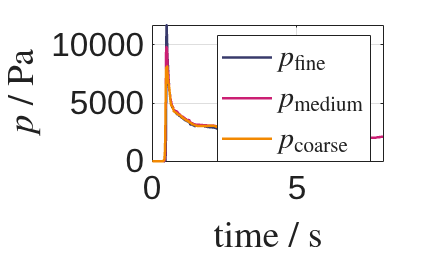

figure
plot(data1(:,tcol), data1(:,col), 'LineWidth', lwidth, 'Color', sblau)
hold on
plot(data2(:,tcol), data2(:,col), 'LineWidth', lwidth, 'Color', smag)
plot(data3(:,tcol), data3(:,col), 'LineWidth', lwidth, 'Color', soran)
hold off, grid on
xlabel('time / s', 'Interpreter', 'latex')
ylabel('$p$ / Pa', 'Interpreter', 'latex'),
legend('$p_\mathrm{fine}$', '$p_\mathrm{medium}$', '$p_\mathrm{coarse}$', 'Interpreter', 'latex');
set(gca, 'FontSize', 20)

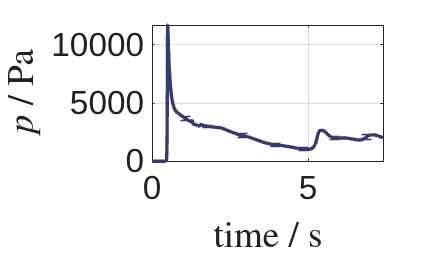

figure
plot(data1(:,tcol), data1(:,col), 'LineWidth', 2, 'Color', sblau)
hold on
errorbar(tq, Phi1, GCI.*Phi1', 'Color', sblau, "LineStyle","none", 'LineWidth', 1)
hold off, grid on
xlabel('time / s', 'Interpreter', 'latex')
ylabel('$p$ / Pa', 'Interpreter', 'latex'),
%legend('$p_\mathrm{fine}$', 'Interpreter', 'latex');
set(gca, 'FontSize', 20)